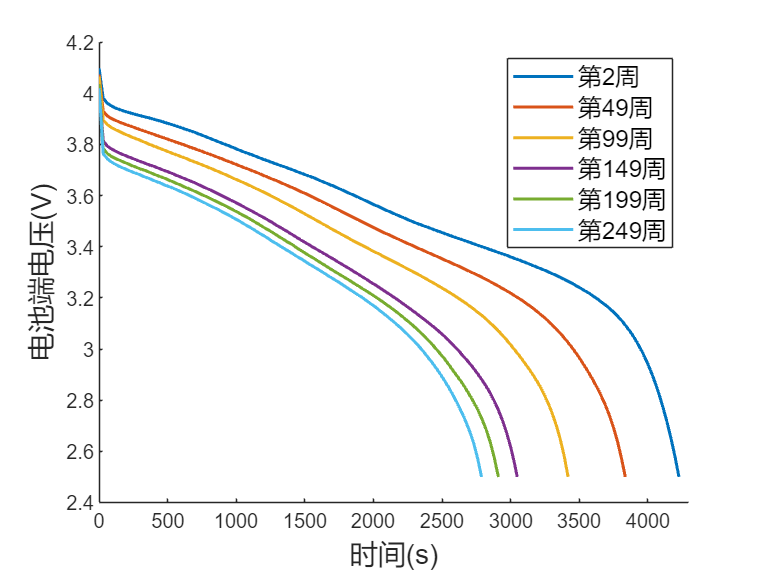

clear;
clc;
load NMC1C_02.mat;
load NMC1C_49.mat;
load NMC1C_99.mat;
load NMC1C_149.mat;
load NMC1C_199.mat;
load NMC1C_249.mat;
load NMC1C_299.mat;

figure(1);
clf;
hold on;
plot(NMC1C_02.Tim,NMC1C_02.Vol,'LineWidth',1.5);
plot(NMC1C_49.Tim,NMC1C_49.Vol,'LineWidth',1.5);
plot(NMC1C_99.Tim,NMC1C_99.Vol,'LineWidth',1.5);
plot(NMC1C_149.Tim,NMC1C_149.Vol,'LineWidth',1.5);
plot(NMC1C_199.Tim,NMC1C_199.Vol,'LineWidth',1.5);
plot(NMC1C_249.Tim,NMC1C_249.Vol,'LineWidth',1.5);
xlim([0,4300]);
% plot(NMC1C_299.Tim,NMC1C_299.Vol,'LineWidth',1.5);
legend('第2周','第49周','第99周','第149周','第199周','第249周',fontsize=12);
xlabel('时间(s)','fontsize',14);
ylabel('电池端电压(V)','fontsize',14);

SOH=[NMC1C_02.Cap(end),NMC1C_49.Cap(end),NMC1C_99.Cap(end),NMC1C_149.Cap(end),NMC1C_199.Cap(end),NMC1C_249.Cap(end),NMC1C_299.Cap(end)]/NMC1C_02.Cap(end)

SOH =             1      0.90747      0.80913      0.72119      0.68861       0.6596      0.57889


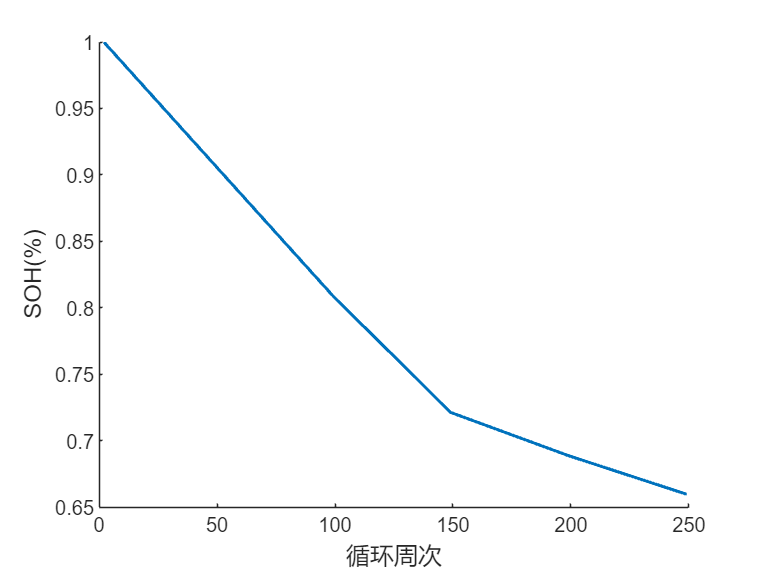

cycleno=[2,49,99,149,199,249,299];
figure(2);
clf;
hold on;
plot(cycleno(1:end-1),SOH(1:end-1),'LineWidth',1.5);
xlabel('循环周次','fontsize',12);
ylabel('SOH(%)','fontsize',12);